clear all
close all

# Trajectory Generation (drone landing)

The problem at hand is defined as follows:


$$\[
\min_{x,u,t_f}  J = t_f \, ,
\]$$


subject to


$$\begin{array}{rcl}
& & \dot x_1= x_4 \, , \quad \dot x_2 = x_5 \, , \quad \dot x_3 = x_6 \, ,   \\
& & \dot x_4  = u_1 \, , \quad \dot x_5 = u_2 \, , \quad { \dot x_6  = -g + u_3 }\, ,  \\
& & x_{10}  = 1 \, \quad  x_{20} = 2 \, , \quad  x_{30} = 3 \, , r \\
& & x_{40}  = -1 \, , \quad  x_{50} = -1 \, , \quad  x_{60} = -1 \, , r \\
& & x_{1}(t_f)  = x_{2}(t_f) = x_{3}(t_f) = 0 \, ,  \\
& & x_{4}(t_f)  = x_{5}(t_f) = x_{6}(t_f) = 0 \, ,  \\
& & { |u_1(t)| \le 1\, , \quad  |u_2(t)| \le 1 \, , \quad  |-g+u_3(t)| \le 1 } \, , \quad  \forall t \in[0,t_f] \, . 
\end{array}$$


Here x1, x2, x3, x4, x5, x6, u1, u2, u3 are vectors with N+1 elements. So the dimension of the problem is 9*(N+1)+1 (the last 1 is final time tf).

The derivative is computed using the squared differentiation matrix for Bernstein polynomials (though this is very similar to simple Euler differentiation). See details in [1].

The problem can be found in [2].

[1] Calvin Kielas-Jensen, Venanzio Cichella, Thomas Berry, Isaac Kaminer, Claire Walton, and Antonio Pascoal. "Bernstein Polynomial-Based Method for Solving Optimal Trajectory Generation Problems." *Sensors* 22, no. 5 (2022): 1869.

[2] Venanzio Cichella, Isaac Kaminer, Claire Walton, Naira Hovakimyan, and António Pascoal. "Consistency of Approximation of Bernstein Polynomial-Based Direct Methods for Optimal Control." *Machines* 10, no. 12 (2022): 1132.

## Load Parameters

CONSTANTS.N = 5; 

Here N is the order of approximation. You can get more accurate results for larger N, at the expense of computational time. For example, we can try plot N=5, 50, 150 and see how your implementations do. With this implementation it always finds the solutions. The computational times are t=0.2s, 6s, and 270s, respectively, and costs f = 3s, 2.7591s, and 2.7474s, respectively.

N = CONSTANTS.N;
CONSTANTS.init = [1;2;3;-1;-1;-1];
CONSTANTS.fin = [0;0;0;0;0;0];
CONSTANTS.umax = 1;

## Initial guess

x1 = linspace(CONSTANTS.init(1),CONSTANTS.fin(1),N+1)';
x2 = linspace(CONSTANTS.init(2),CONSTANTS.fin(2),N+1)';
x3 = linspace(CONSTANTS.init(3),CONSTANTS.fin(3),N+1)';
x4 = linspace(CONSTANTS.init(4),CONSTANTS.fin(4),N+1)';
x5 = linspace(CONSTANTS.init(5),CONSTANTS.fin(5),N+1)';
x6 = linspace(CONSTANTS.init(6),CONSTANTS.fin(6),N+1)';
u1 = zeros(N+1,1);
u2 = zeros(N+1,1);
u3 = zeros(N+1,1);
T = 1;
x0 = [x1;x2;x3;x4;x5;x6;u1;u2;u3;T];

## Linear Constraints and UL Bounds

A=[]; b=[]; Aeq=[]; beq=[]; lb=[]; ub=[]; 

## Optimize

options = optimoptions(@fmincon,'Algorithm','sqp','MaxFunctionEvaluations',3000000);
tic
[x,fval] = fmincon(@(x)costfun(x,CONSTANTS),x0,A,b,Aeq,beq,lb,ub,@(x)nonlcon(x,CONSTANTS),options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 0.184416 seconds.


## Plot

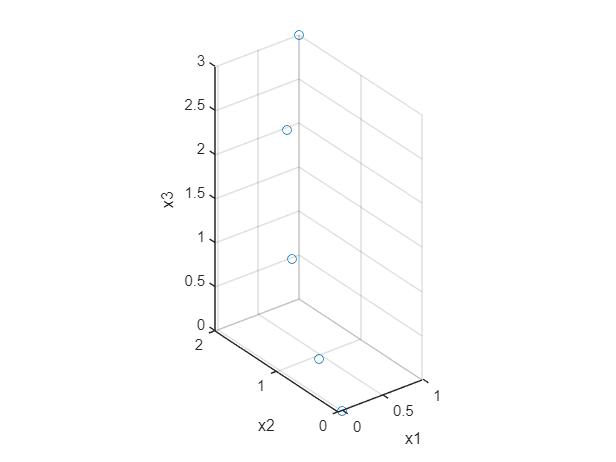

N = CONSTANTS.N;

%% Grab Trajectories

x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
x3 = x(2*N+3:3*N+3);
x4 = x(3*N+4:4*N+4);
x5 = x(4*N+5:5*N+5);
x6 = x(5*N+6:6*N+6);
u1 = x(6*N+7:7*N+7);
u2 = x(7*N+8:8*N+8);
u3 = x(8*N+9:9*N+9);
T = x(end);

[tnodes,w,Diff] = BeBOT(CONSTANTS.N,T);


%% Plot
t = 0:0.01:T;
figure
plot3(x1,x2,x3,'o'); hold on
xlabel('x1'); ylabel('x2'); zlabel('x3')
grid on
axis equal

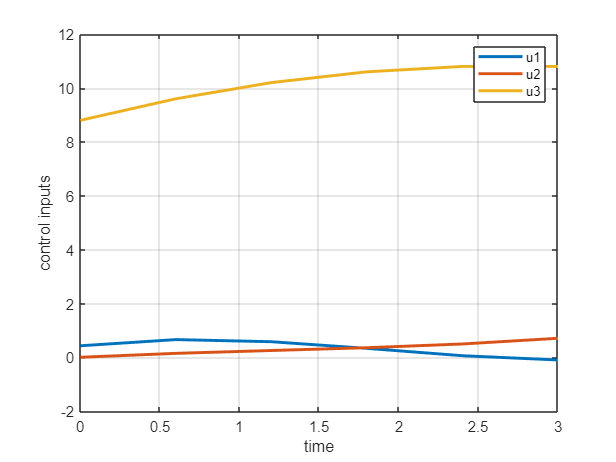

figure
plot(tnodes,u1,'Linewidth',2); hold on
plot(tnodes,u2,'Linewidth',2);
plot(tnodes,u3,'Linewidth',2);
xlabel('time'); ylabel('control inputs'); 
legend('u1','u2','u3');
grid on

## Cost Function

function J = costfun(x,CONSTANTS)
%COSTFUN Summary of this function goes here
N = CONSTANTS.N; 
x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
x3 = x(2*N+3:3*N+3);
x4 = x(3*N+4:4*N+4);
x5 = x(4*N+5:5*N+5);
x6 = x(5*N+6:6*N+6);
u1 = x(6*N+7:7*N+7);
u2 = x(7*N+8:8*N+8);
u3 = x(8*N+9:9*N+9);
T = x(end);

J = T;
end

## Nonlinear Constraints

function [c,ceq] = nonlcon(x,CONSTANTS)
%NONLCON Summary of this function goes here
%   Detailed explanation goes here
N = CONSTANTS.N;
x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
x3 = x(2*N+3:3*N+3);
x4 = x(3*N+4:4*N+4);
x5 = x(4*N+5:5*N+5);
x6 = x(5*N+6:6*N+6);
u1 = x(6*N+7:7*N+7);
u2 = x(7*N+8:8*N+8);
u3 = x(8*N+9:9*N+9);
T = x(end);

[~,~,Diff] = BeBOT(N,T);
 
dyn1 = x1'*Diff - x4';
dyn2 = x2'*Diff - x5';
dyn3 = x3'*Diff - x6';
dyn4 = x4'*Diff - u1';
dyn5 = x5'*Diff - u2';
dyn6 = x6'*Diff - u3' + 9.8*ones(1,N+1);





c=[u1-CONSTANTS.umax;-u1-CONSTANTS.umax;u2-CONSTANTS.umax;-u2-CONSTANTS.umax;-9.8+u3-CONSTANTS.umax;9.8-u3-CONSTANTS.umax;];
ceq=[dyn1';dyn2';dyn3';dyn4';dyn5';dyn6'; ... 
    x1(1)-CONSTANTS.init(1);x2(1)-CONSTANTS.init(2);x3(1)-CONSTANTS.init(3); ...
    x4(1)-CONSTANTS.init(4);x5(1)-CONSTANTS.init(5);x6(1)-CONSTANTS.init(6); ...
    x1(end)-CONSTANTS.fin(1);x2(end)-CONSTANTS.fin(2);x3(end)-CONSTANTS.fin(3); ...
    x4(end)-CONSTANTS.fin(4);x5(end)-CONSTANTS.fin(5);x6(end)-CONSTANTS.fin(6); ...
    ];

end

## Functions:

function [tnodes,w,Dm] = BeBOT(N,T)
% derivative of a Bezier curve
% INPUT
% N: order of the curve
% T: tf-t0
% OUTPUT
% tnodes: equidistant time nodes
% w: integration weights
% Dm: differentiation matrix for Bernstein polynomials of order N 

% HOW TO USE:
% If Cp are the control points of the Bernstein polyomial (horizontal
% vector), then the integral from t0 to tf is Cp*w;
% If Cp are the control points of the Bernstein polyomial (horizontal vector), then the control points
% its derivative are Cpdot = Cp*Dm
% NOTE: Cpdot are control points of a Bernstein poly of order N. In order words, 
% degree elevation is performed on Dm

tnodes = linspace(0,T,N+1);
w = T/(N+1)*ones(N+1,1);
Dm = BernsteinDifferentiationMatrix(N,T)*DegElevMatrix(N-1,N);


end










function Dm = BernsteinDifferentiationMatrix(N,T)
% derivative of a Bezier curve
% INPUT
% N: order of the curve
% T: tf-t0
% OUTPUT
% Dm: differentiation matrix for Bernstein polynomials of order N 

% HOW TO USE:
% If Cp are the control points of the Bernstein polyomial, then the control points
% its derivative are Cpdot = Cp*Dm
% NOTE: Cpdot are control points of a Bernstein poly of order N-1. To
% obtain Cpdot of order N, degree elevation must be performed, i.e. Cpdot =
% Cp*Dm*DegElevMatrix(N-1,N)


Dm = -[N/T*eye(N); zeros(1,N)]+[zeros(1,N);N/T*eye(N)];

end





function E = DegElevMatrix(N,M)
% INPUT: N: Order of the curve to be elevated; M: order to which it has to
% be elevated;
% OUTPUT: Elevation matrix E. 
% HOW TO USE: Given a Bernstein poly of order N with control points cpN (row vector),
% the control points of the Bernstein poly degree elevated to order N,
% namely cpM (row vector) is given by cpM = cpN*E;

% Written by: Venanzio Cichella       

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



r = M-N;

for i = 1:1:N+1
    for j = 1:1:r+1
         E(i+j-1,i) = nchoosek_mod(N,i-1)*nchoosek_mod(r,j-1)/nchoosek_mod(M,i+j-2);
    end
end

E = E';


end






function binom = nchoosek_mod(N,k)
% This function produces the same output as MATLAB's nchoosek, but it's more efficient 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

binom = 1;
    for j = 1:k
        binom = binom*(N-(k-j));
        binom = binom/j;
    end
end